1、已知 a =17.2, b = 4。 计算下列算式并显示结果


$$c=\;\sqrt[3]{a+9\ldotp 8}$$



$$d=10\cdot \sqrt{5b+16}$$


a=17.2

a = 17.2000

b=4

b = 4

c=(a+9.8)^(1/3)

c = 3

d=10*(5*b+16)^(1/2)

d = 60

2、利用sin及cos函数画圆

k=0:0.0001:pi*2

k =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


x=cos(k)

x =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


y=sin(k)

y =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


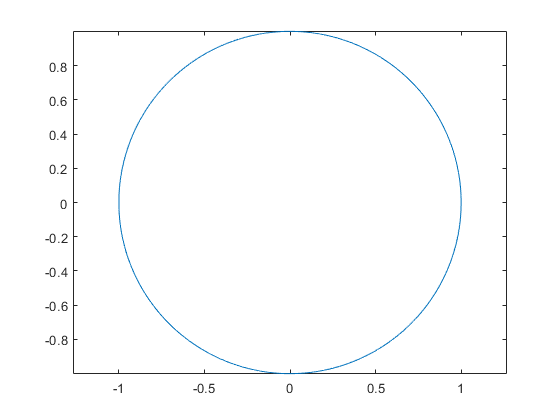

plot(x,y)
axis equal

3、求解方程组


$${\left\{\begin{array}{c}
3x+2y-z=10\\
-x+3y+2z=5\\
x-y-z=-1
\end{array}\right)}$$


a. 将方程组转化成矩阵形式

b. 使用matlab求解方程组

A=[3,2,-1;-1,3,2;1,-1,-1]

A =      3     2    -1
    -1     3     2
     1    -1    -1


b=[10;5;-1]

b =     10
     5
    -1


x=lsqr(A,b)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 4.9e-14。


x =    -2.0000
    5.0000
   -6.0000


4、外部数据获取（不要修改获取的数据的值）

a.读入Array.mat，并显示其中的两个变量vector及matrix

b. 将vector中第3、6、9、12个数赋给vectorA，并显示结果

c. 将vector中的第4个数修改为12后赋值于vectorB，并显示结果

d. 将matrix的第5，6，7行赋予matrixA，并显示结果

e.将matrix的第1，2行及第2，3列赋予matrixB，并显示结果 

f. 找出matrix中小于3的值的位置

load Array
vector

vector =      4    -4     3    -3     2     2    -1     0    -4     4     0     5


matrix

matrix =     -1     2    -4     5     4
    -2    -3     4    -2    -3
     3     3     5    -4    -2
    -4     3     1    -1    -4
     3    -3     3     1    -5
     4     3     2    -5     5
     0    -5     4     5    -4
    -3     4    -2     2    -4
     1    -1     0     2     4
     0     2    -4     0     4


vectorA=vector(3:3:12)

vectorA =      3     2    -4     5


vector(4)=12

vector =      4    -4     3    12     2     2    -1     0    -4     4     0     5


vectorB=vector

vectorB =      4    -4     3    12     2     2    -1     0    -4     4     0     5


matrixA=matrix(5:7,:)

matrixA =      3    -3     3     1    -5
     4     3     2    -5     5
     0    -5     4     5    -4


matrixB=matrix(1:2,2:3)

matrixB =      2    -4
    -3     4


find(matrix<3)

ans =      1
     2
     4
     7
     8
     9
    10
    11
    12
    15


5、读入excel数据分析

t=readtable("data.xlsx","VariableNamingRule","preserve")

t = 13×3 table
        月份         销售额（万元）    占总产值百分比
    _____________    ____________    ____________

    {'1月'      }         100            NaN     
    {'2月'      }         520            NaN     
    {'3月'      }         800            NaN     
    {'4月'      }        1500            NaN     
    {'5月'      }        1320            NaN     
    {'6月'      }        1100            NaN     
    {'7月'      }         875            NaN     
    {'8月'      }         987            NaN     
    {'9月'      }         652            NaN     
    {'10月'     }        1300            NaN     
    {'11月'     }        1600            NaN     
    {'12月'     }         970            NaN     
    {'销售总额：'}       11724            NaN     


for ind=1:13
    t{ind,3}=t{ind,2}/t{13,2};
end
disp(t)

        月份         销售额（万元）    占总产值百分比
    _____________    ____________    ____________

    {'1月'      }         100         0.0085295  
    {'2月'      }         520          0.044353  
    {'3月'      }         800          0.068236  
    {'4月'      }        1500           0.12794  
    {'5月'      }        1320           0.11259  
    {'6月'      }        1100          0.093825  
    {'7月'      }         875          0.074633  
    {'8月'      }         987          0.084186  
    {'9月'      }         652          0.055612  
    {'10月'     }        1300           0.11088  
    {'11月'     }        1600           0.13647  
    {'12月'     }         970          0.082736  
    {'销售总额：'}       11724                 1  



6、不同方案的比价

各市场对应物品价格：

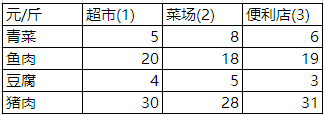

每日采购数量：

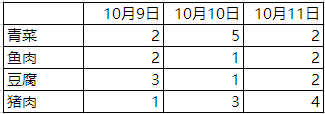

请根据运行结果给出每日购物地点建议。

price=[5,8,6;20,18,19;4,5,3;30,28,31];
sum=[2,5,2;2,1,2;3,1,2;1,3,4];
for day=1:3
    s=sum(:,day);
    minimum=233333333;
    target=0;
    for market=1:3
        p=price(:,market);
        if dot(s,p)<minimum
            minimum=dot(s,p);
            target=market;
        end
    end
    disp(["day",day,"to market",target])
end

    "day"    "1"    "to market"    "3"

    "day"    "2"    "to market"    "1"

    "day"    "3"    "to market"    "2"



即：

10.9    便利店

10.10  超市

10.11  菜场